# **Introduction to FMINCON**

Minimize the function $f(x)=x_1^2 +x_2^2$


$$x_1 +x_2 \le 1$$



$$x_1 \;\ge \;0$$



$$x_2 \ge 0$$


**Setup of Key Parameters**

% Define the objective function
objective = @(x) (x(1)-pi)^2 + (x(2)-exp(1))^2;

% Define the inequality constraints (A * x <= b)
A = [1, 1];
b = 1;

% Define the lower bounds (x >= lb)
lb = [0, 0];

% Initial guess
x0 = [0.5, 0.5];

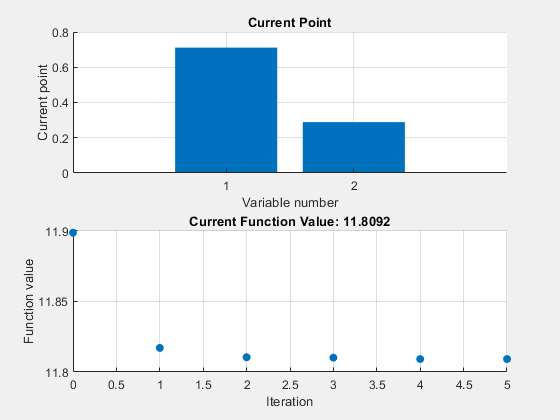


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Set nondefault solver options
options2 = optimoptions("fmincon","PlotFcn",["optimplotx","optimplotfval"]);

% Solve
[solution,objectiveValue] = fmincon(objective,x0,A,b,[],[],zeros(size(x0)),...
    Inf(size(x0)),[],options2);


% Clear variables
clearvars options2

**Initialize a figure for the animation**

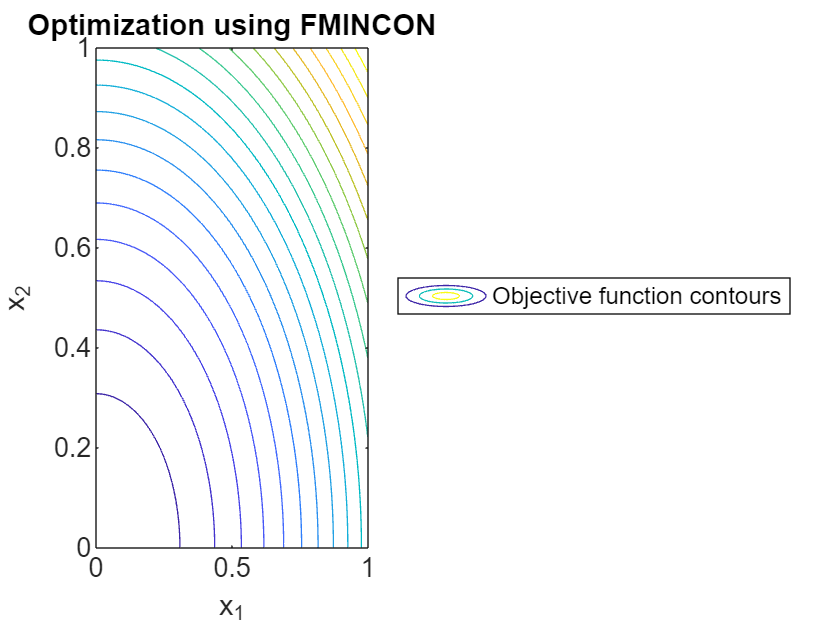

figure;
[X1, X2] = meshgrid(0:0.01:1, 0:0.01:1);
F = X1.^2 + X2.^2;
contour(X1, X2, F, 20);
hold on;
xlabel('x_1');
ylabel('x_2');
title('Optimization using FMINCON');
legend('Objective function contours', 'Location', 'eastoutside');

**Optimization**

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.189879e+01    0.000e+00    5.223e-01
    1       6    1.181708e+01    0.000e+00    3.196e-01    3.607e-01
    2       9    1.181046e+01    0.000e+00    2.882e-02    4.714e-02
    3      12    1.181019e+01    0.000e+00    1.021e-03    1.495e-02
    4      15    1.180919e+01    0.000e+00    1.039e-04    7.620e-04
    5      18    1.180919e+01    0.000e+00    2.000e-06    4.204e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

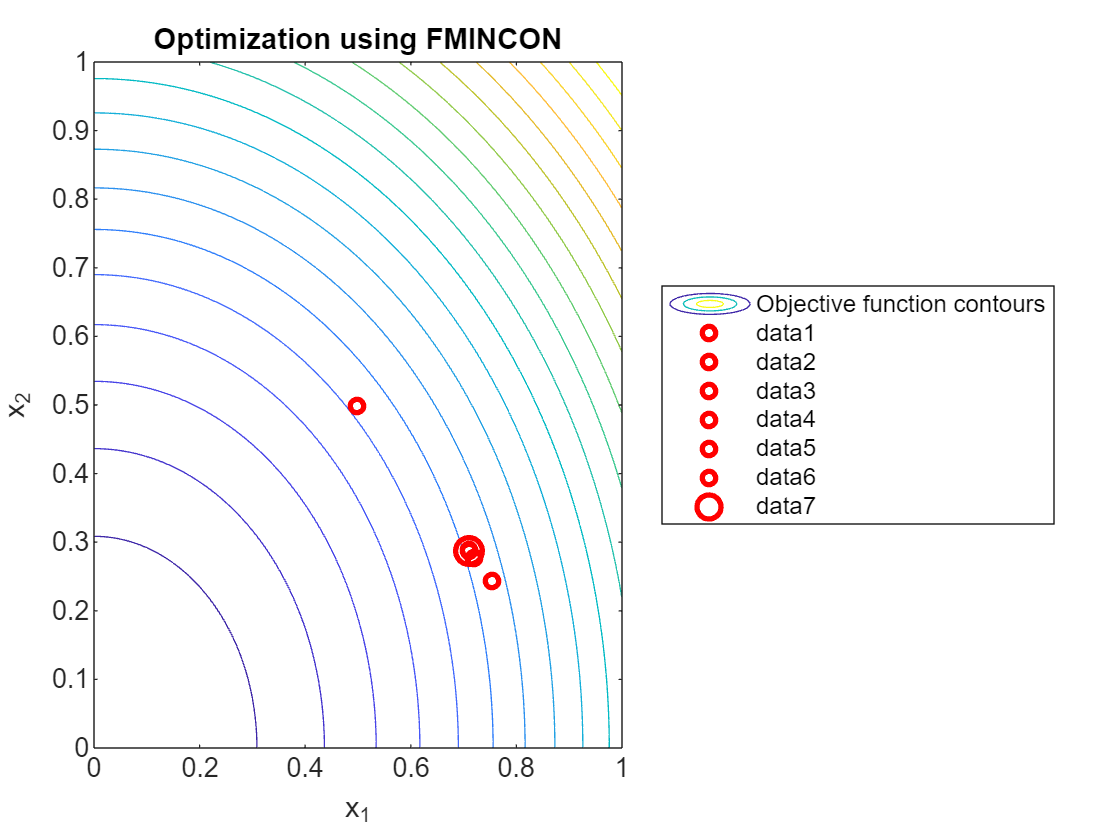

% Call fmincon to minimize the objective function
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point', 'OutputFcn', @outfun);
[x, fval, exitflag, output] = fmincon(objective, x0, A, b, [], [], lb, [], [], options);

% Display the results
disp('Optimal solution:')

Optimal solution:


disp(x)

    0.7117    0.2883



disp('Function value at optimal solution:')

Function value at optimal solution:


disp(fval)

   11.8092



**Plotting Function**

function stop = outfun(x,optimValues,state)
    stop = false; % You can stop the optimization if you set this to true
    switch state
        case 'init'
            % Initial plot setup
            hold on;
        case 'iter'
            % Plot each iteration point
            plot(x(1), x(2), 'ro', 'MarkerSize', 5, 'LineWidth', 2);
            drawnow;
        case 'done'
            % Plot the final point
            plot(x(1), x(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
            hold off;
    end
end